clc
clear
close all
% 养成好习惯

% err = 1e-5;
T1 = pi:-0.02:pi/2-72*0.02; %赋予theta 值，主动件
% a = 0.884
% T1 = a*pi
% T1 = .75*pi
istrue = []; % 判断L6、L7是否能形成三角形
X2 = [];
Y2 = [];
X3 = [];
Y3 = [];
X5 = zeros(1,length(T1));
Y5 = zeros(1,length(T1));
X10 = zeros(1,length(T1));
Y10 = zeros(1,length(T1));
x0 = 0;
y0 = 0;
X0 = zeros(1,length(T1));
Y0 = X0;
l2 = 105;
l3 = 102.88;
l4 = 136;
l5 = l4-40;
l6 = 86;
l7 = 41;
l8 = 84.65;
l9 = 34.2;
tt = 7; %23杆和36杆夹角、角度制
t7 = 17;%尖端偏角、角度制
x1 = x0 + 116;
y1 = y0 + 37;
X1 = ones(1,length(T1))*x1;
Y1 = ones(1,length(T1))*y1;
for t1 = T1
    x2 = x0+l2*cos(t1); %关节2
    y2 = y0+l2*sin(t1);
    X2 = [X2, x2];
    Y2 = [Y2, y2];
    xot = optimvar('xot',2); %解关节3
    eq1 = l2*cos(t1)+l3*cos(xot(2)) == x1+l4*cos(xot(1));
    eq2 = l2*sin(t1)+l3*sin(xot(2)) == y1+l4*sin(xot(1));
    prob = eqnproblem;
    prob.Equations.eq1 = eq1;
    prob.Equations.eq2 = eq2;
    x00.xot = [t1 pi/6];
    [sol,fval,exitflag] = solve(prob,x00);
    t2 = x00.xot(1);
    X3 = [X3 x3(x1,l4,t2)];
    Y3 = [Y3 y3(y1,l4,t2)];
end

Solving problem using fsolve.

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Solving problem using fsolve.

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the <a h

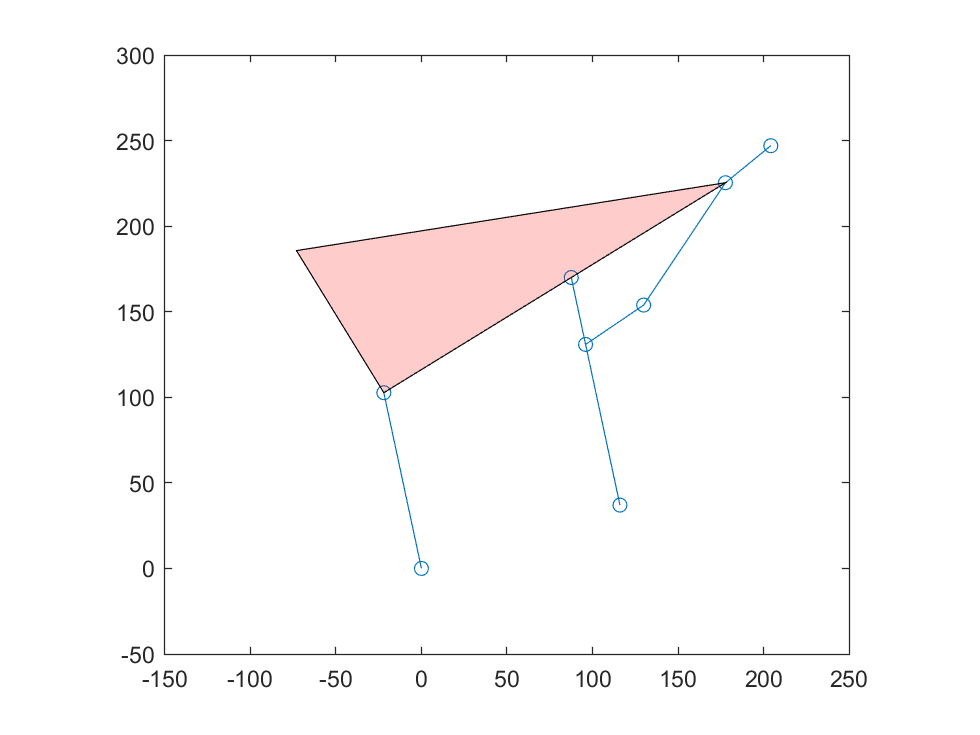

X4 = X3+(X1-X3)*(l4-l5)/l4; %利用比例解出节点4
Y4 = Y3+(Y1-Y3)*(l4-l5)/l4;
X6 = X2+(X3-X2)*(l3+l8)/l3; %利用比例解出节点6
Y6 = Y2+(Y3-Y2)*(l3+l8)/l3;
% t4 = atand((Y6-Y5)./(X6-X5)); 
% t9 = t4-t7;
% X7 = X6+l9*cosd(t9); %计算末端偏置
% Y7 = Y6+l9*sind(t9);

for i = 1:length(T1)
    istrue = [istrue l7+l6 > sqrt((X6(i)-X4(i))^2+(Y6(i)-Y4(i))^2)];% 判断L6、L7是否能形成三角形
    if(l7+l6 > sqrt((X6(i)-X4(i))^2+(Y6(i)-Y4(i))^2))
        % 利用两圆交点解出节点5
        syms x y
        eqn1 = (x-X4(i))^2+(y-Y4(i))^2-l7^2 == 0;
        enq2 = (x-X6(i))^2+(y-Y6(i))^2-l6^2 == 0;
        S = vpasolve(eqn1,enq2,x,y,[X3(i)+(X1(i)-X3(i))*l5/l4;X3(i)+(X1(i)-X3(i))*l5/l4]);
        % 会有两解，靠下（y较小）的点为需要的点
        Y5(i) = min(double(S.y(1)),double(S.y(2)));
        X5(i) = double(S.x(find(Y5(i) == [double(S.y(1)),double(S.y(2))])));
        t4 = atand((Y6(i)-Y5(i))./(X6(i)-X5(i))); 
        t9 = t4-t7;
        X7(i) = X6(i)+l9*cosd(t9); %计算末端偏置
        Y7(i) = Y6(i)+l9*sind(t9);

        X10(i) = X2(i)-78*(Y3(i)-Y2(i))/l3;
        Y10(i) = Y2(i)+78*(X3(i)-X2(i))/l3;
        clf
        % 绘制杆件
        plot([X0(i),X2(i),X3(i),X1(i),X4(i),X5(i),X6(i),X3(i),X6(i),X7(i)],...
            [Y0(i),Y2(i),Y3(i),Y1(i),Y4(i),Y5(i),Y6(i),Y3(i),Y6(i),Y7(i)],'o-')
        hold on
        clear alpha
        % 绘制扰流板
        fi = fill([X2(i),X10(i),X6(i)],[Y2(i),Y10(i),Y6(i)],'r');
        alpha(0.2);
    end
    % 保证坐标系不变形
    axis equal
    xlim([-150,250])
    ylim([-50,300])
    hold on
    % 停留0.5秒
    pause(0.5)
end

function x3 = x3(x1,l4,t2)
% 计算节点3横坐标
x3 = x1+l4*cos(t2);
end

function y3 = y3(y1,l4,t2)
% 计算节点3纵坐标
y3 = y1+l4*sin(t2);
end
